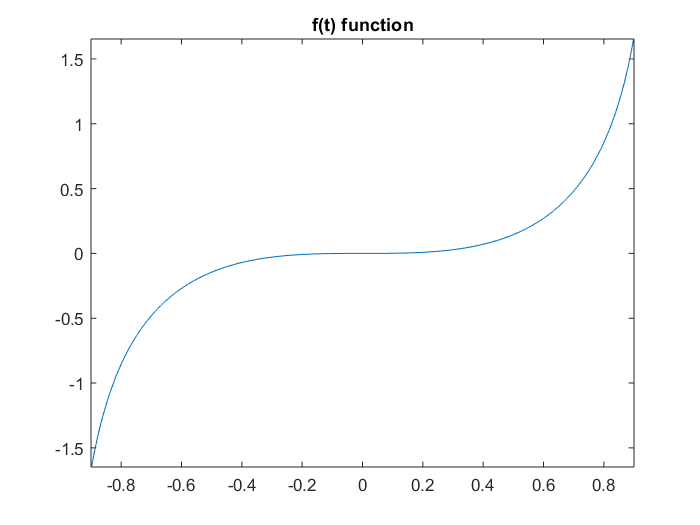

format long
syms f(t)

% the given function  and the decorator
f(t) = t.^3./(1-t.^2).^(1/2);
p = @(t) t.^3./(1-t.^2).^(1/2);

% step size
h = 0.01;

% set the bounds to the given points 
a = 0;
b = 1;

% plot the function 
fplot(f(t))
title('f(t) function')

% find the actual answer for the function going to from the bounds
actual = integral(p,0,1)

actual =    0.666666666666744


actual1 = int(f,0,1)

$$actual1 = \frac{2}{3}$$


% to have h = 0.01, that means N_m = 100
h = 0.01;
% so the number of segments is equal 
N_m = 100;
% set the sum of areas to 0
M = 0;

% do the one run for the set values
% find the step size which should = 0.01
dx = (b-a)/N_m;
for i=1:N_m
    % calculate the midpoint formula at each segment and sum the area
    % under the curve
    x = a + 0.5*(2*i-1)*dx;        
    M = M + f(x)*dx;
end

% display the error and the answer
relativeError = double(abs(M-actual)/actual)

relativeError =    0.064336380514477


M = double(M)

M =    0.623775746323754
